clc,close all,clear all;

dir = 'image/56.jpg'

dir = 'image/56.jpg'

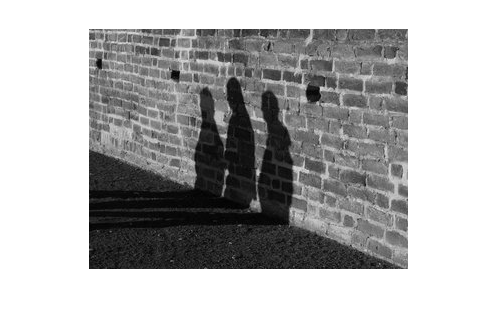

x=imread(dir);
x=rgb2gray(x);

% FFT
xf = fft2(double(x));
xf1 = abs(xf); %幅度
xf2 = angle(xf); %相位

imshow(x)

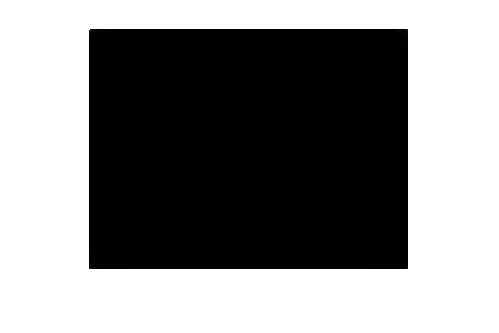

imshow(xf1,[])

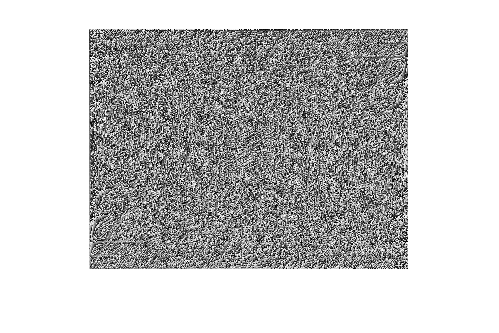

imshow(xf2,[])

参考资料

https://blog.csdn.net/songzitea/article/details/17319769

https://www.peterkovesi.com/matlabfns/index.html#phasecong

img=imread(dir);
% phaseCong = phasecongmono(rgb2gray(img));
phaseCong=phasecong3(img);

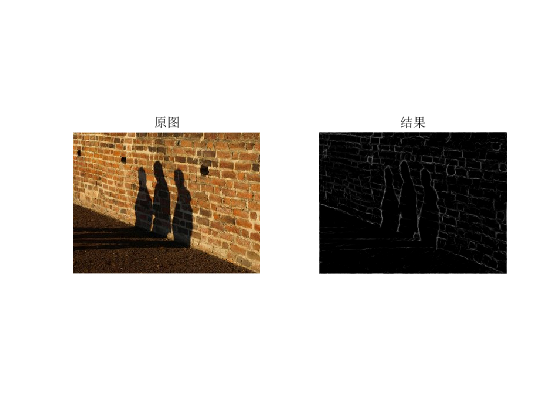

figure,
subplot(121),imshow(img),title('原图');
subplot(122),imshow(phaseCong),title('结果');


imwrite(phaseCong,'a.jpg')